clear;
close all;

theta = linspace(-pi/2, pi/2, 100);

phi0 = 1;
mu = 1;

phi1 = phi0.*(cos(theta).^mu);

phi0 = 1.5;
mu = 1;

phi2 = phi0.*(cos(theta).^mu);

phi0 = 1;
mu = 4;

phi3 = phi0.*(cos(theta).^mu);

figure()
polarplot(theta, phi1, 'b-'); hold on;
polarplot(theta, phi2, 'k-'); hold on;
polarplot(theta, phi3, 'g-'); hold on;

ax = gca;

ax.ThetaLim = [-90,90];
ax.ThetaZeroLocation = 'top';
rruler = ax.RAxis;
rruler.Label.String = '\phi(\theta)'

rruler =   NumericRuler with properties:

             Limits: [0 1.5000]
              Scale: 'linear'
           Exponent: 0
         TickValues: [0 0.5000 1 1.5000]
    TickLabelFormat: '%g'

  Show all properties



rruler = ax.ThetaAxis;
rruler.Label.String = '\theta'

rruler =   NumericRuler with properties:

             Limits: [-90 90]
              Scale: 'linear'
           Exponent: 0
         TickValues: [-90 -60 -30 0 30 60 90]
    TickLabelFormat: '%g'

  Show all properties


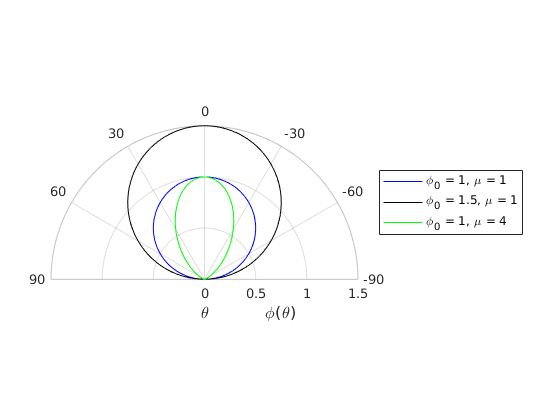


legend('\phi_0 = 1, \mu = 1', '\phi_0 = 1.5, \mu = 1', '\phi_0 = 1, \mu = 4');